# Practica 6: DFT y IDFT

*Edkir Uriel nava mendez #15*

*Diego castro elvira #3*

*Paso 1. *Calcula la Transformada Discreta de Fourier (DFT) de cada una de las siguientes secuencias x[n]

a) 

x = [1,-1]; 
fft(x) 

ans =      0     2


b)

x = [1,1,-1,-1]; 
fft(x) 

ans =    0.0000 + 0.0000i   2.0000 - 2.0000i   0.0000 + 0.0000i   2.0000 + 2.0000i


c)

x = [3,-1,4,2]; 
fft(x) 

ans =    8.0000 + 0.0000i  -1.0000 + 3.0000i   6.0000 + 0.0000i  -1.0000 - 3.0000i


d)

x = [1,0,0,-1,0,0]; 
fft(x) 

ans =      0     2     0     2     0     2


Paso 2. Dada la secuencia de longitud 𝑁=4, definida por $x[n]=cos(\frac{\pi}{2} n)$ para 𝑛= 0,1,2,3 calcula su Transformada Discreta de Fourier (DFT).

n=[0,1,2,3]

n =      0     1     2     3


x=cos(pi*n/2)

x =     1.0000    0.0000   -1.0000   -0.0000


N=length(x);
X = zeros(1, N);
for k=1:N
    for n=1:N
        X(k)=X(k)+x(n)*exp((-2*pi*j/N)*((n-1)*(k-1)));
    end
end
k=0:N-1;
disp('Resultado:');

Resultado:


disp(X);

  -0.0000 + 0.0000i   2.0000 - 0.0000i   0.0000 - 0.0000i   2.0000 + 0.0000i



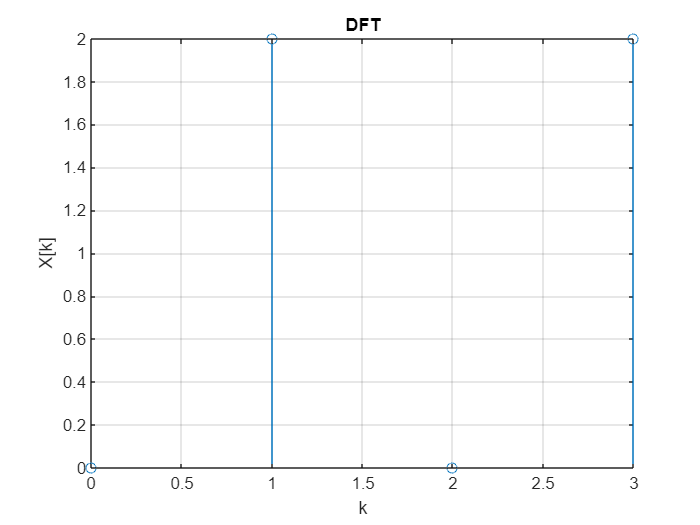

abs(X(k+1));
figure(1);
stem(k,abs(X(k+1)));
grid;
xlabel('k');
ylabel('X[k]');
title('DFT');
hold off;

%Comprobando con la funcion directa en matlab
fft(x)

ans =   -0.0000 + 0.0000i   2.0000 - 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i


Paso 3. Calcula la Transformada Discreta Inversa de Fourier (IDFT) de las secuencias:

a)

xa=[0,2];
N=length(xa);
x = zeros(1, N);
for n=1:N
    for k=1:N
        x(n)=x(n)+xa(k)*exp((2*pi*1i*(k-1)*(n-1))/N);
    end
end
n=0:N-1;
y=1/N*x(n+1);
disp(y);

   1.0000 + 0.0000i  -1.0000 + 0.0000i



b)

xb=[0,-2j,0,2j];
N=length(xb);
x = zeros(1, N);
for n=1:N
    for k=1:N
        x(n)=x(n)+xb(k)*exp((2*pi*1i*(k-1)*(n-1))/N);
    end
end
n=0:N-1;
y=1/N*x(n+1);
disp(y);

   0.0000 + 0.0000i   1.0000 - 0.0000i  -0.0000 + 0.0000i  -1.0000 + 0.0000i



c)

xc=[0,4,0,0,4];
N=length(xc);
x = zeros(1, N);
for n=1:N
    for k=1:N
        x(n)=x(n)+xc(k)*exp((2*pi*1i*(k-1)*(n-1))/N);
    end
end
n=0:N-1;
y=1/N*x(n+1);
disp(y);

   1.6000 + 0.0000i   0.4944 - 0.0000i  -1.2944 + 0.0000i  -1.2944 + 0.0000i   0.4944 - 0.0000i



Paso 4. Complete la definición de la función *dtft* 

% Define una función anónima f(t)
f = @(t) sinc(t);
% Establece el período de muestreo T
T = 0.1;
% Establece el número de muestras a incluir a cada lado de 0 en la suma DTFT
N = 10;
% Crea un vector de frecuencias en las que muestrear la DTFT
W = linspace(-pi, pi, 101); % En este caso, muestrearemos en el rango [-pi, pi]
% Llama a la función DTFT para calcular la DTFT muestreada
F = DTFT(f, T, N, W)

F =    4.5309 + 0.0000i   4.7318 - 0.0000i   4.9344 + 0.0000i   5.1386 + 0.0000i   5.3439 + 0.0000i   5.5502 - 0.0000i   5.7573 + 0.0000i   5.9649 - 0.0000i   6.1727 - 0.0000i   6.3805 + 0.0000i   6.5880 - 0.0000i   6.7950 + 0.0000i   7.0011 + 0.0000i   7.2061 - 0.0000i   7.4098 + 0.0000i   7.6118 - 0.0000i   7.8119 - 0.0000i   8.0099 - 0.0000i   8.2054 + 0.0000i   8.3982 - 0.0000i   8.5879 - 0.0000i   8.7745 + 0.0000i   8.9575 - 0.0000i   9.1368 + 0.0000i   9.3120 - 0.0000i   9.4829 + 0.0000i   9.6493 + 0.0000i   9.8110 + 0.0000i   9.9676 - 0.0000i  10.1190 + 0.0000i  10.2650 + 0.0000i  10.4053 - 0.0000i  10.5397 - 0.0000i  10.6680 + 0.0000i  10.7901 - 0.0000i  10.9057 - 0.0000i  11.0147 + 0.0000i  11.1170 - 0.0000i  11.2122 + 0.0000i  11.3004 - 0.0000i  11.3814 - 0.0000i  11.4551 - 0.0000i  11.5213 + 0.0000i  11.5799 + 0.0000i  11.6310 + 0.0000i  11.6743 - 0.0000i  11.7098 - 0.0000i  11.7375 - 0.0000i  11.7573 - 0.0000i  11.7692 - 0.0000i


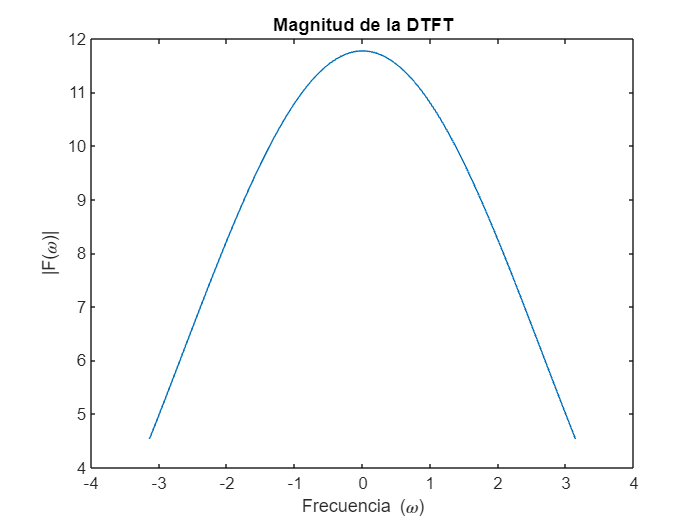

% Grafica la magnitud de la DTFT
figure;
plot(W, abs(F));
title('Magnitud de la DTFT');
xlabel('Frecuencia (\omega)');
ylabel('|F(\omega)|');

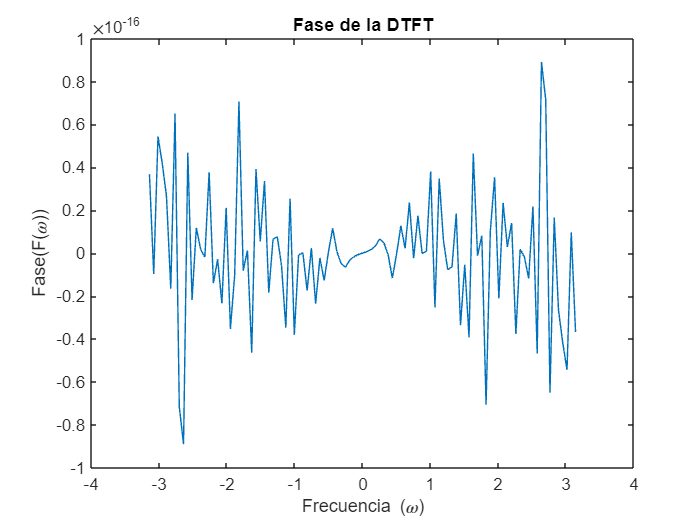


% Grafica la fase de la DTFT
figure;
plot(W, angle(F));
title('Fase de la DTFT');
xlabel('Frecuencia (\omega)');
ylabel('Fase(F(\omega))');

function F = DTFT(f, T, N, W)
    F = zeros(size(W));
    % Calcula el rango de muestras a incluir en la suma DTFT
    n = -N : N;
    % Itera a través de las frecuencias en W
    for k = 1:length(W)
        % Calcula la DTFT en la frecuencia W(k)
        F(k) = sum(f(n * T) .* exp(-1j * W(k) * n * T));
    end
end